# Multivariate Pathway Identification (MPathI): A Tutorial

This tutorial explains the MPathI method in [Kragel et al. 2021, Neuron](https://www.sciencedirect.com/science/article/pii/S0896627321004165)*.*

[Kragel, Philip A., Marta Čeko, Jordan Theriault, Danlei Chen, Ajay B. Satpute, Lawrence W. Wald, Martin A. Lindquist, Lisa Feldman Barrett, and Tor D. Wager. 2021. “A Human Colliculus-Pulvinar-Amygdala Pathway Encodes Negative Emotion.” *Neuron* 109 (15): 2404–12.e5.](https://www.sciencedirect.com/science/article/pii/S0896627321004165)

It is also used in [this paper](https://www.biorxiv.org/content/10.1101/2021.05.02.442354v1.abstract) in eLife. 

The key concepts behind this method are that:

(1) Brain pathways are natural units of analysis in the search for brain correlates of perception, behavior, and mental states. 

(2) Multivariate patterns linked to population codes in specific neural ensembles are a more targeted and powerful unit of analysis than averages over gross anatomical regions.

While many fMRI studies have examined connectivity between regions, they typically use average activity within large regions (many brain voxels). However, many studies on multivariate pattern analysis have shown that patterns provide more sensitive and specific links to perception, behavior, and mental states (e.g., see [this](https://www.nature.com/articles/nn.4478/boxes/bx1), [this](https://www.sciencedirect.com/science/article/pii/S089662731830477X), [this](https://www.sciencedirect.com/science/article/pii/S1364661306001847), and [this](https://www.science.org/doi/full/10.1126/science.1152876)).  And neuron-level imaging, electrophysiology, and manipulations show that behaviors and functional pathways are mediated by specific cell ensembles that often include a minority of cells in an anatomical region (e.g., [this](https://www.nature.com/articles/npp2015358), [this](https://www.science.org/doi/full/10.1126/science.aap8586), and [this)](https://www.nature.com/articles/35039062). 

The MPathI method therefore attempts to identify multivariate patterns across voxels in each of two regions, where the patterns are chosen to maximize connectivity across the pattern response (a proxy for neural population code) across regions. Thus, rather than identifying patterns based on relationships with psychological variables, MPathI identifies them based on interconnectivity across brain regions. The result is identification of a functional pathway based on connectivity in neural subpopulations.

The method for running MPathI is called `model_brain_pathway`. This is a method for the CANlab fmri_data object.  

## 1. Introduction

**Pathways are a critical unit of analysis.** The brain is organized into parthways and circuits. Neurons in a given anatomical area (e.g., the pulvinar nucleus of the thalamus) are functionally diverse.  Particular ensembles of neurons are responsive to particular stimuli and drive particular behaviors. These ensembles also project to specific subpopulations in other brain regions (e.g., from the pulvinar to specific parts of the amygdala). In nonhuman animals, it is increasingly possible to tag these cell ensembles based on transcriptional markers or activity in particular task or environmental states, and to identify their precise projections to different brain areas. The functional pathway is a critical unit of analysis.  They define the systems studied in systems neuroscience.  Often, it is possible to evoke or suppress a behavior by activating or inhibiting neurons at multiple points along a pathway or within a neural circuit.

**Human measures of functional connectivity lack specificity.** In humans, tools for identifying precise connections among neural ensembles are not available. Analyses of "functional connectivity" typically focus on correlations in signal across pre-defined regions of interest (ROIs). Typically, signals are averaged over an entire ROI (e.g., pulvinar, or basolateral amygdala), and correlations among region-averaged signals are estimated. There are many variants on the correlations--bivariate correlations, partial correlations, Granger causal models, Dynamic Causal Models, and more--but the principle of averaging over voxels in a region is common to all of them. The averaging process inevitably averages over multiple neural subpopulations with different functional profiles and different connectivity with other regions, resulting in a lack of both functional and neuroanatomical specificity.

**MPathI applies principles of MVPA to connectivity analysis, identifying functional pathways with more precision than using anatomical ROIs.** A large body of work on Multivariate Pattern Analysis (MVPA) has shown that it is possible to obtain subtantially improved functional sensitivity and specificity by optimizing patterns to (a) discriminate stimuli or tasks, or to (b) predict behaviors and other outcomes. Patterns can be assessed at (a) the group (or population) level, with pattern weights constrained to be identical across persons, or (b) the individual-person level, with pattern weights varying across persons. Each has important strengths and weaknesses. The idea of MPathI, and similar approaches in its class, is to identify multivariate patterns in two regions such that the functional association between 'pattern responses' (or scores) across regions is maximized. The pattern in each region is intended to be a more precise characterization of activity in a subpopulation of neurons that are connected to subpopulations in other regions. This may not always be the case, and its benefits over using ROI averages (or first principal components) depend on the spatial distributions of relevant neural subpopulations and the functional resolution of the images. However, our analyses to date show substantial benefits.

**MPathI can be used to identify pathways, which can subsequently be tested for their relationships to mental states and behaviors.** One strategy is to first use MPathI to identify pathways, and then to characterize how those pathways respond to stimuli and correlate with behaviors.  For example, one can identify a pathway based on time series connectivity. This can be done on resting-state data or on task data blind to task state. As many pathways are only activated during relevant tasks, task data may be advantageous here. Then, one can apply the patterns to extract responses in each region and their (often Fisher's Z-transformed) correlation, a measure of connectivity strength. These pathway measures can be correlated with individual differences. In a perhaps more powerful approach, pattern responses and time-varying connectivity (using, e.g., Dynamic Conditional Correlations or sliding windows) can be extracted over time.  These can then be analyzed in relation to within-person stimulus events or behaviors. For example, one could run a regression with pattern response (or dynamic connectivity) as the outcome and stimulus conditions or behaviors as predictors (i.e., a standard fMRI GLM design matrix).  This tests whether pathway-related activity or connectivity is affected by task state. One can also analyze whether responses are sensitive and/or specific to particular task states. 

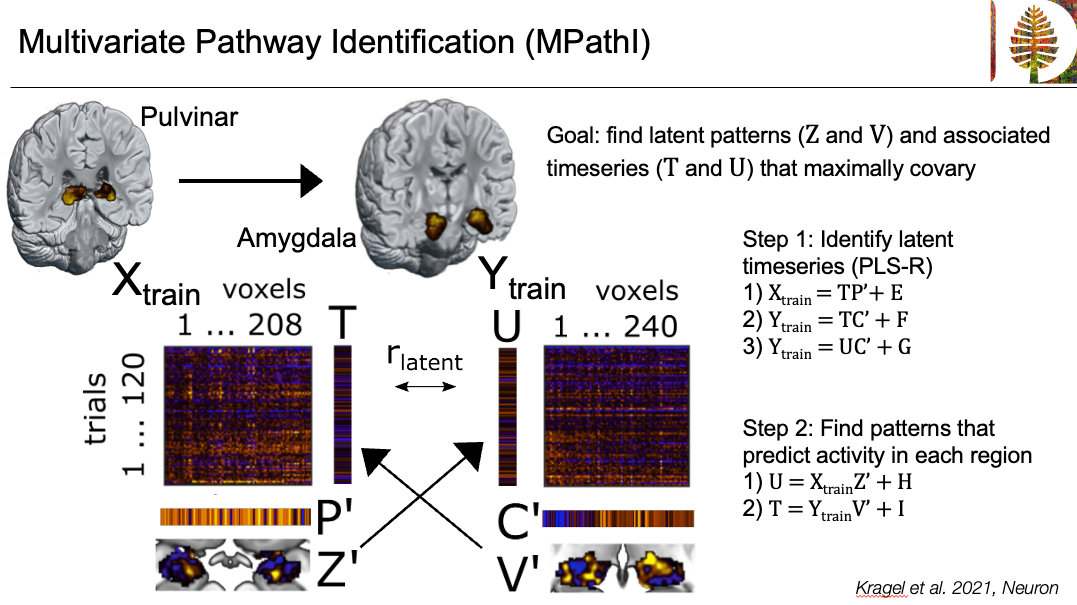

### Multiple ways to use MPathI

You can run MPathI on a **group analysis**, across images from multiple subjects, or **individualized analyses**, in which each subject is run separately with model_brain_pathway and gets their own pattern. You can also use **hyperalignment** in a group analysis to functionally align each subject's functional patterns.

- In **group analysis**, you would stack multiple images per subject into a single analysis. You  specify a variable that indicates which images belong to which subjects, so that models are always trained on some subjects and tested on others, for valid statistics. The latent patterns V and Z are constrained to be the same across individuals.

- In **individualized analysis**, you would run model_brain_pathways separately on time series images from each subject separately. The latent patterns V and Z are different for each individual, making the analysis more robust to inter-individual variability in the location of function regions and/or ideographic topographic patterns. After running the analysis on a series of subjects, you can test the summary connectivity statistics and other properties across individual participants in a second-level summary statistics group analysis.  

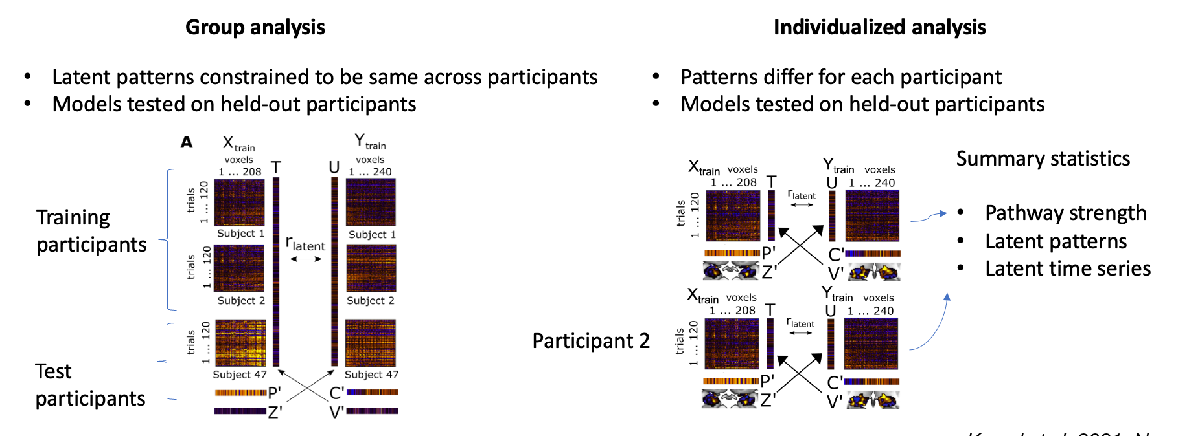

## 2. Installation and code

**Toolbox**: The MPathI method is part of the CANlab Core Tools repository. For code, dependencies, and installation, along with more information on these objects and CANlab tools, see [canlab.github.io](http://canlab.github.io) and the [CANlab Core Tools github repository](https://github.com/canlab/CanlabCore). 

**Code**: The method for running MPathI is called `model_brain_pathway`. This is a method for the CANlab **fmri_data()** class object.  These objects permit interactive analysis with simple commands.

**Usage**: To run `model_brain_pathway`,` y`ou'll pass in an fmri_data object containing the data to extract and run analyses on (`obj_to_analyze`) as the first argument, and CANlab **atlas()** class objects defining the regions to connect.  See the example below.

## 3. Load and prepare a sample dataset

### Load a sample single-trial dataset

The dataset, "bmrk3", has multiple subjects, with brain images modeling single-trial responses to a series of painful thermal stimuli. It is part of a Github repository from CANlab with single-trial pain data from multiple studies.

[https://github.com/canlab/canlab_single_trials](https://github.com/canlab/canlab_single_trials)

A paper describing this dataset and several models trained using it is here:

[Petre, B., Kragel, P., Atlas, L. Y., Geuter, S., Jempa, M., Koban, L., Krishnan, A., Lopez-Sola, M., Losin, E.A.R., Roy, M., Woo, C-W. & Wager, T.D. (2022). A multistudy analysis reveals that evoked pain intensity representation is distributed across brain systems. *PLoS Biol*. 20(5):e3001620. doi: 10.1371/journal.pbio.3001620.](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.3001620)


fname = which('swrsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz');
obj = fmri_data(fname);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 145720800 bytes
Loading image number:   150
Elapsed time is 0.502968 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
.fullpath should have image name for each image column in .dat
Attempting to expand image filenames in case image list is unexpanded 4-D images
Number of unique values in dataset: 493  Bit rate: 8.95 bits


If fname is empty, then the sample data file is not on your Matlab path. Locate it and add the folder to your path like in the example below:

% A few preliminary steps

% Suppress some warnings that are irrelevant for present purposes for this demo
warning('off', 'all'); % Turns off all warnings

% Set a couple of properties to make figures render more nicely in html
set(groot, 'DefaultFigurePosition', [200, 200, 900, 600], 'DefaultAxesFontSize', 12);


### Data cleaning

If you are using time series data, it can be very helpful to high-pass filter the time series and to model and remove outliers. These can otherwise have substantial global impact on your connectivity estimates. 

See 

*canlab_help_prep_for_connectivity.html*

[https://canlab.github.io/_pages/tutorials/html/nuisance_covariates.html](https://canlab.github.io/_pages/tutorials/html/nuisance_covariates.html)

*canlab_connectivity_preproc()*

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | rmssd | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 22.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
Framewise Displacement (before and after >0.50 mm correction):
  0 images 
                               Outlier_c

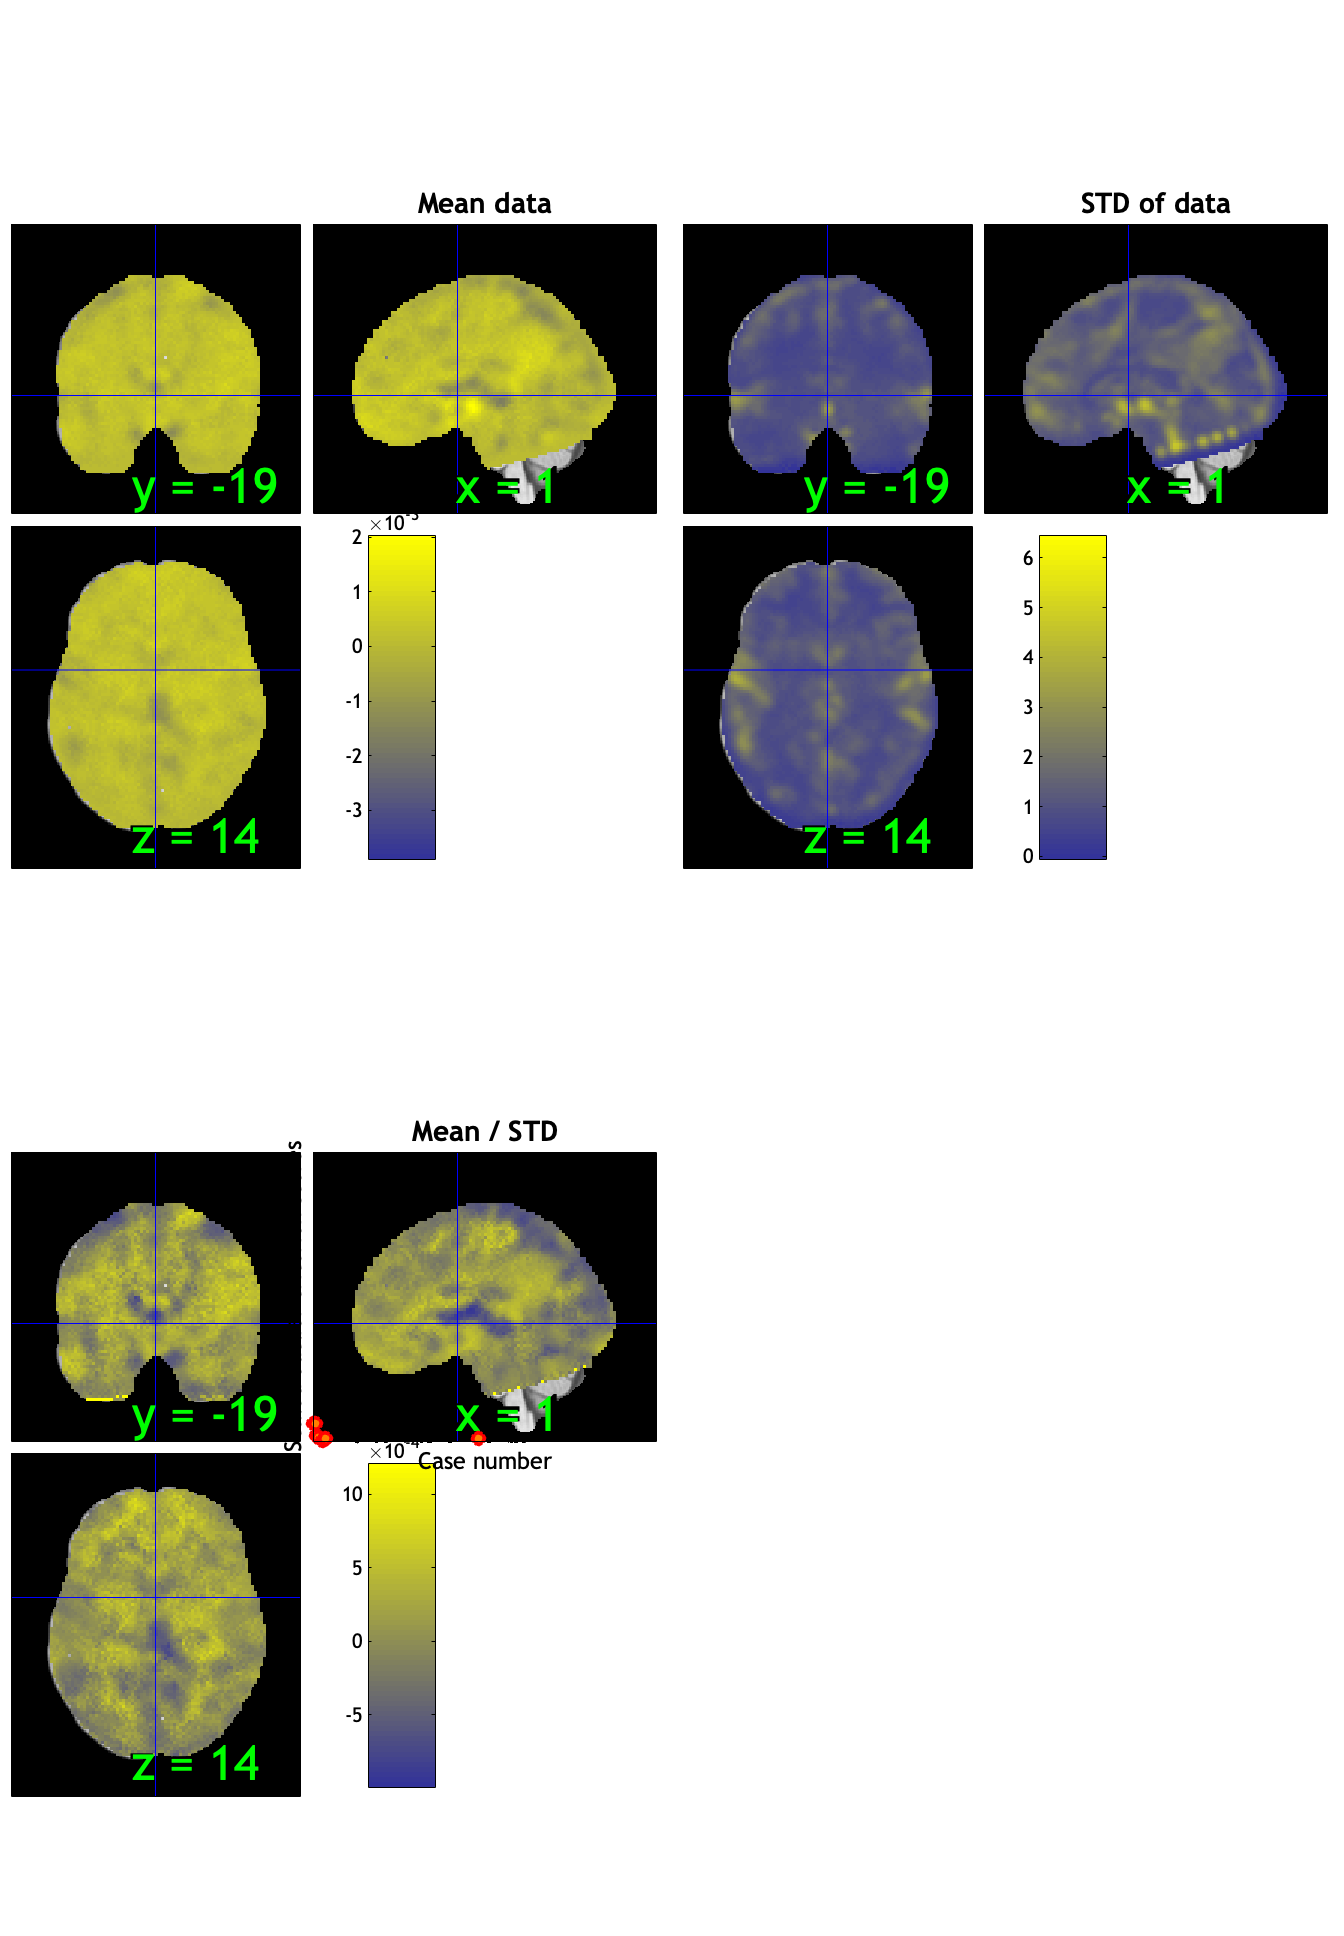

ans = 10

Extracting from gray_matter_mask_sparse.img.
Removing 2565 voxels with one or more NaNs
Extracting from canonical_white_matter.img.
Removing 106 voxels with one or more NaNs
Extracting from canonical_ventricles.img.
Removing 158 voxels with one or more NaNs


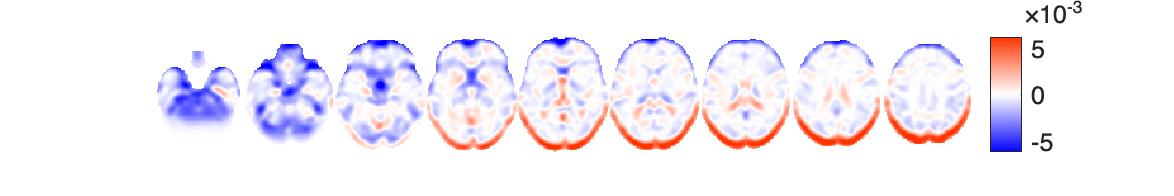

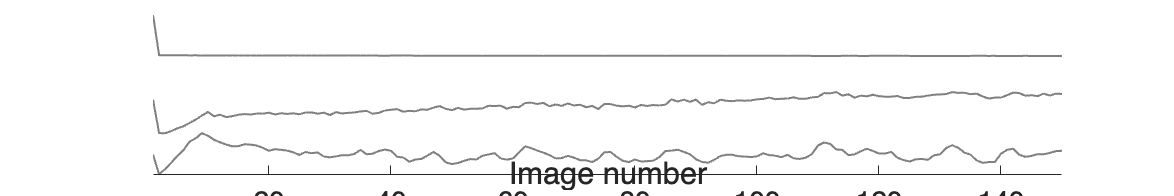

mvmtfname = which('rp_sub-sid001567_task-pinel_acq-s1p2_run-03_bold.txt');


obj_denoised = clean_fmri_timeseries(obj, mvmtfname);


**Inspect data**

**Now show a plot of the denoised data to check it visually**

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 




Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.67%
Expected 7.50 outside 95% ellipsoid, found  12

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 12 images		Cases 61 62 74 95 96 97 102 103 121 128 129 139 



Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 58.00%
Expected 7.50 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  0 images 
                               Outlier_count    Percentage
                               _____________    __________

    global_mean                      4            2.6667  
    global_mean_to_variance          1           0.66667  
    missing_values                   0                 0  
    rmssd_dvars                      0                 0  
    spatial_variability             11            7.3333  
    mahal_cov_uncor                 12                 8  
    maha

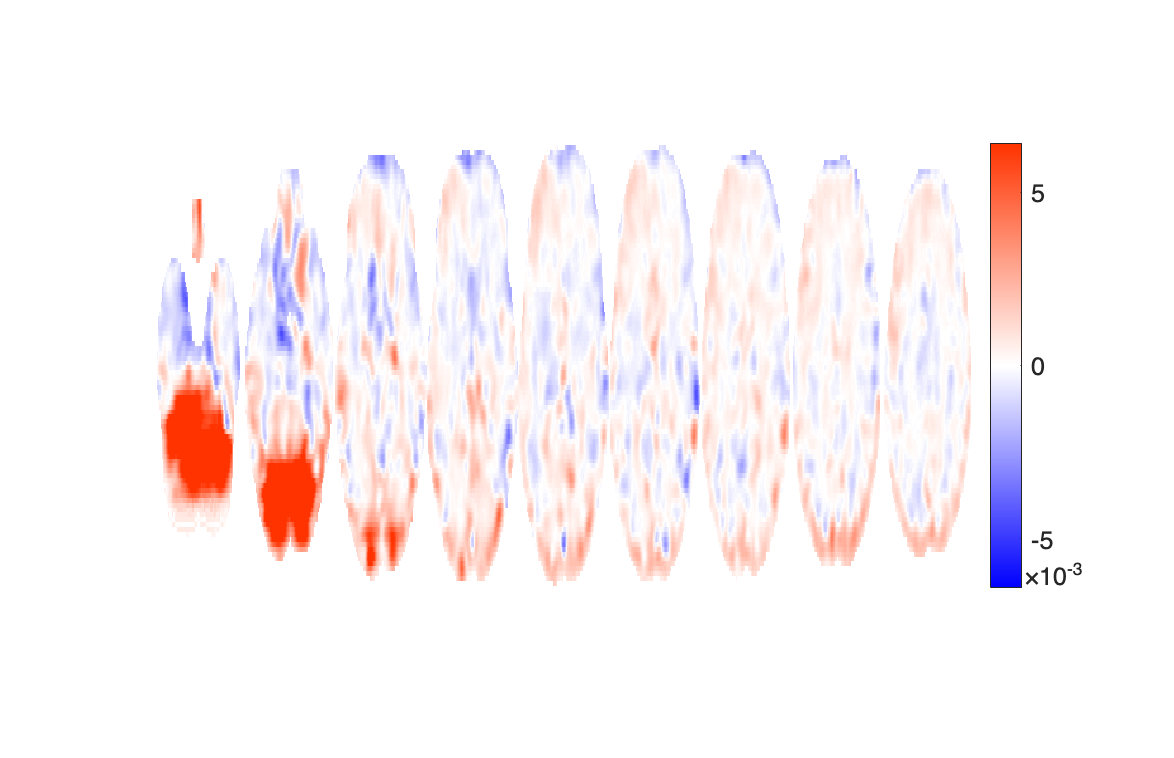

Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions


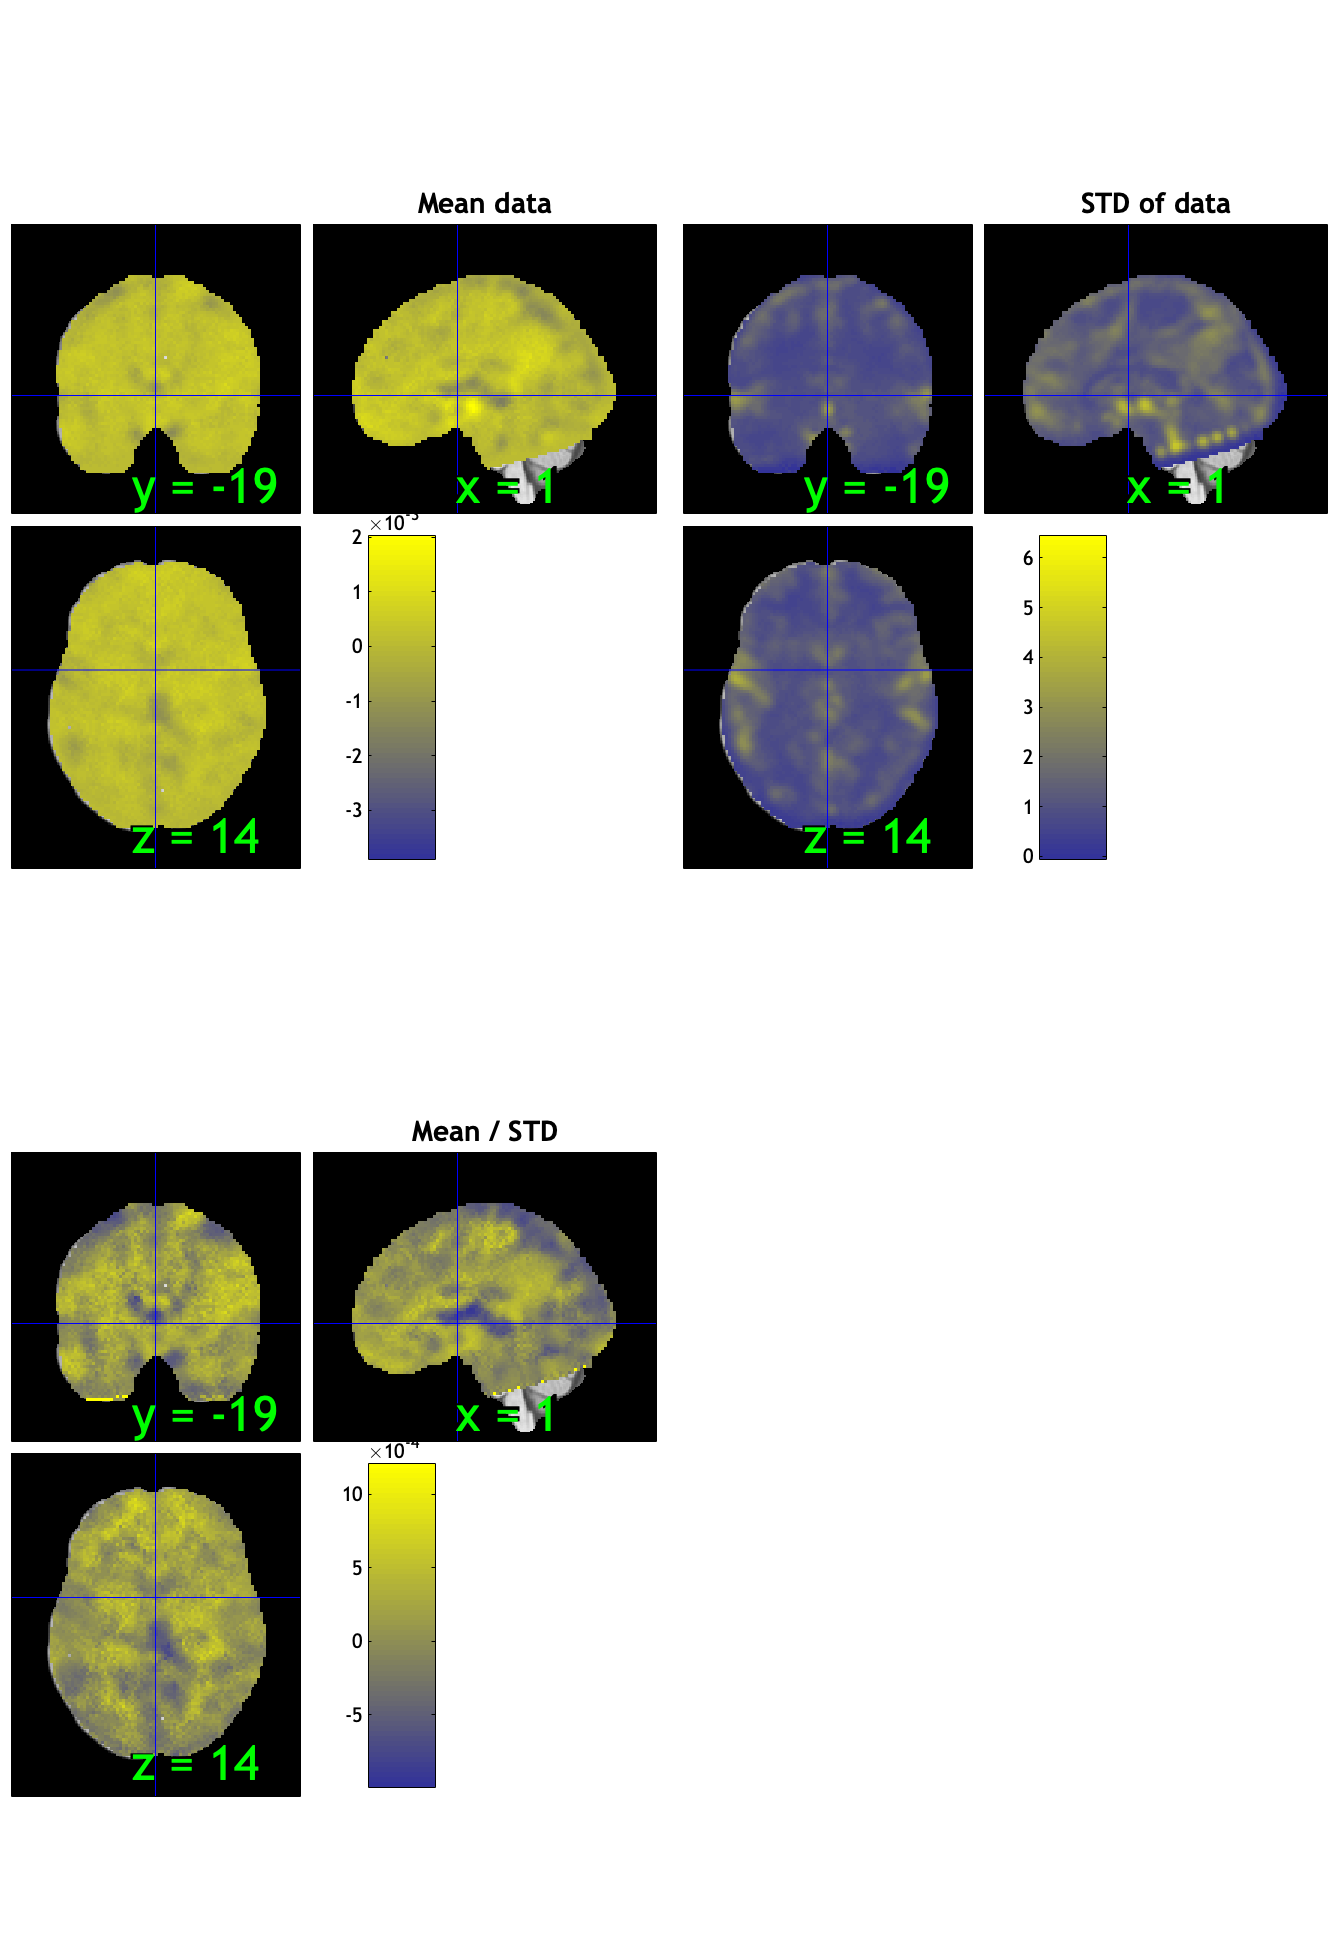

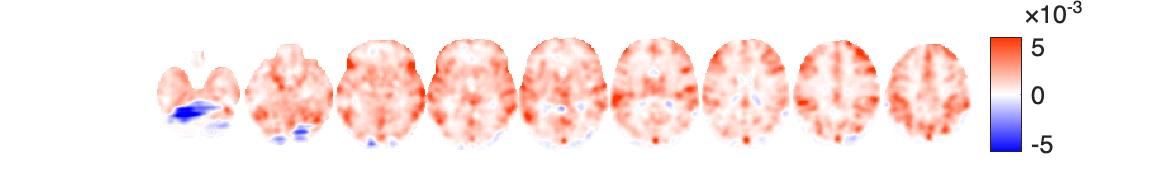

plot(obj_denoised);

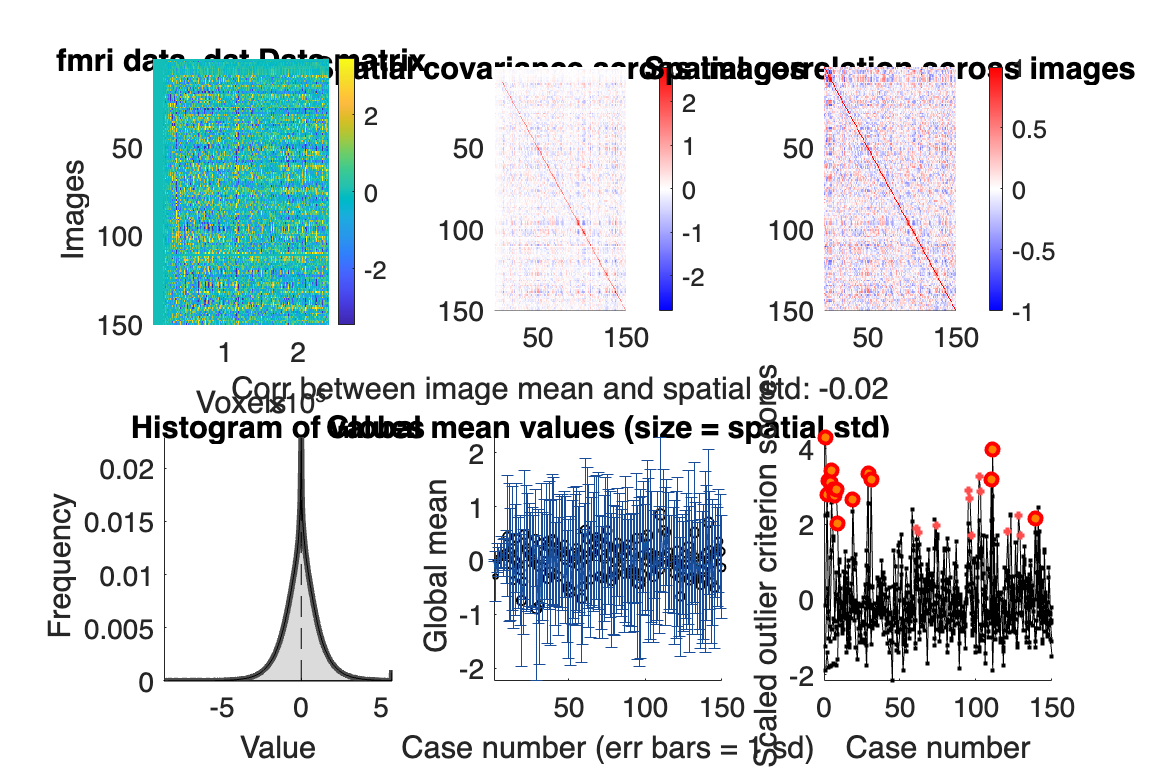

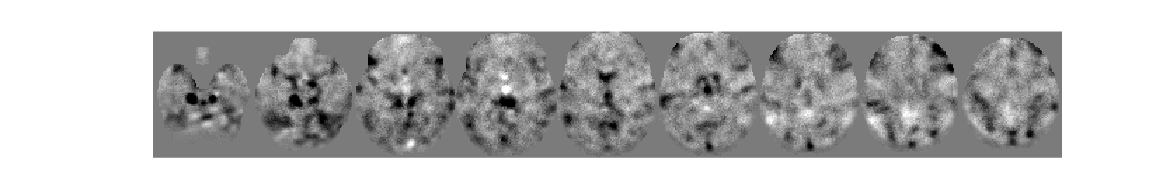

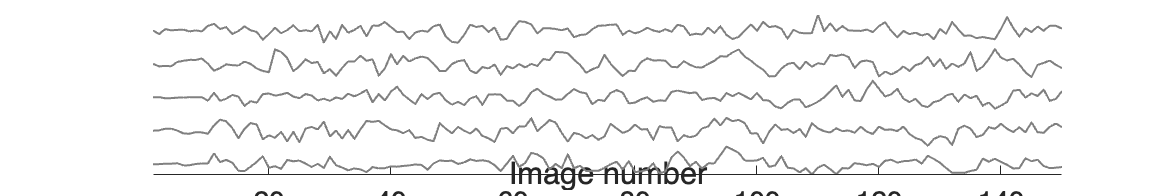

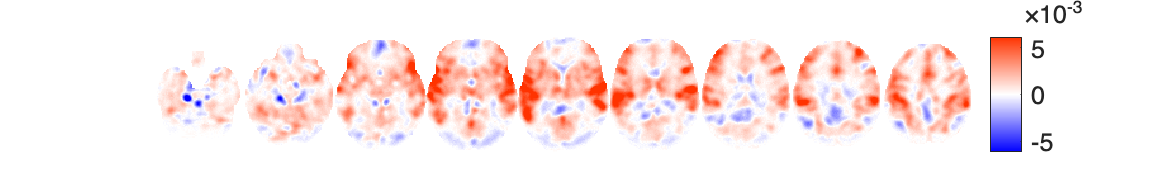

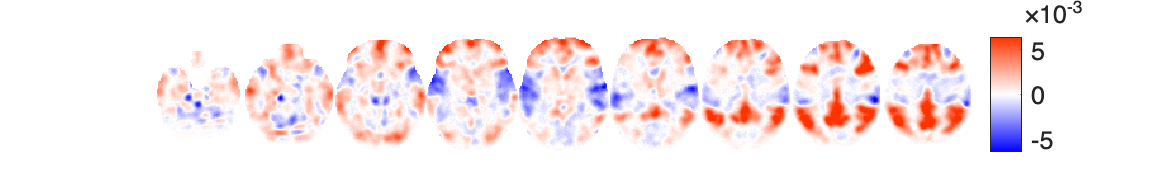

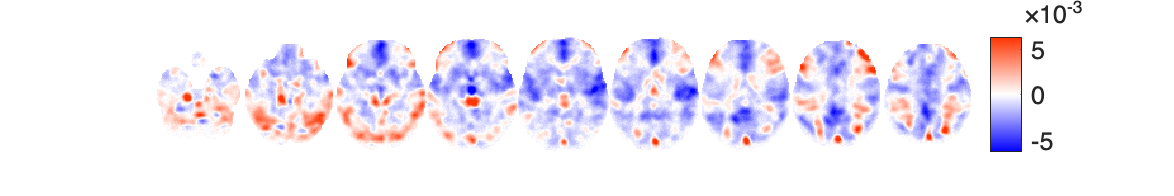

% Have a look at principal components of the denoised data

pca(obj_denoised, 'k', 5);

## 4. Load atlas and select regions

MPathI, as implemented in the `fmri_data.model_brain_pathway` method, takes four regions as inputs.This is intended to test two target pathways, each containing two regions, and whether "on-target" connectivity in expected pathways is stronger than "off-target" connectivity in crossed pathways.

Here, we are interested in two pathways: The visual thalamocortical pathway, from LGN to V1, and the auditory thalamocortical pathway, from MGN to A1.  These are well established sensory pathways. The visual pathway is ipsilateral, as it decussates at the optic chiasm before reaching the thalamus. The auditory pathway is more bilateral.

Region selection is accomplished here using the CANlab `atlas` object. The ROIs come from (1) SPM anatomy toolbox (amygdala and posterior insula); (2)  the Szekely / Morel thalamic atlas (VPL); and (3) a hand-drawn PBN region based on reported PBN coordinates from Fairhurs et al. 2007.  See `help canlab_load_ROI` and the* .references* field of the `atlas_obj` for more information. 

**Considerations:**

- You can run MPathI on a **group analysis**, across images from multiple subjects, or **individualized analyses**, in which each subject is run separately with model_brain_pathway and gets their own pattern.

- MPathI can identify a pattern in a subset of voxels. This can help make group analysis robust to mis-specification of regions.  It can also make individualized analyses robust to inter-individual variation in the locations or patterns of functional regions across subjects.

- It is sometimes helpful to specify regions that are somewhat larger, particularly if the location of atlas regions relative your individual participants' functional areas is uncertain (e.g., due to mis-registration, distortions in BOLD images, and inter-individual variability). This can come at a cost in the precision of localization but can increase power.

atlas_obj = load_atlas('canlab2024');

Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat


atlas_obj.labels  % see all labels

ans = 1×518 cell array
    {'Ctx_V1_L'}    {'Ctx_MST_L'}    {'Ctx_V6_L'}    {'Ctx_V2_L'}    {'Ctx_V3_L'}    {'Ctx_V4_L'}    {'Ctx_V8_L'}    {'Ctx_4_L'}    {'Ctx_3b_L'}    {'Ctx_FEF_L'}    {'Ctx_PEF_L'}    {'Ctx_55b_L'}    {'Ctx_V3A_L'}    {'Ctx_RSC_L'}    {'Ctx_POS2_L'}    {'Ctx_V7_L'}    {'Ctx_IPS1_L'}    {'Ctx_FFC_L'}    {'Ctx_V3B_L'}    {'Ctx_LO1_L'}    {'Ctx_LO2_L'}    {'Ctx_PIT_L'}    {'Ctx_MT_L'}    {'Ctx_A1_L'}    {'Ctx_PSL_L'}    {'Ctx_SFL_L'}    {'Ctx_PCV_L'}    {'Ctx_STV_L'}    {'Ctx_7Pm_L'}    {'Ctx_7m_L'}    {'Ctx_POS1_L'}    {'Ctx_23d_L'}    {'Ctx_v23ab_L'}    {'Ctx_d23ab_L'}    {'Ctx_31pv_L'}    {'Ctx_5m_L'}    {'Ctx_5mv_L'}    {'Ctx_23c_L'}    {'Ctx_5L_L'}    {'Ctx_24dd_L'}    {'Ctx_24dv_L'}    {'Ctx_7AL_L'}    {'Ctx_SCEF_L'}    {'Ctx_6ma_L'}    {'Ctx_7Am_L'}    {'Ctx_7PL_L'}    {'Ctx_7PC_L'}    {'Ctx_LIPv_L'}    {'Ctx_VIP_L'}    {'Ctx_MIP_L'}    {'Ctx_1_L'}    {'Ctx_2_L'}    {'Ctx_3a_L'}    {'Ctx_6d_L'}    {'Ctx_6mp_L'}    {'Ctx_6v_L'}    {'Ctx_p24pr_L'}    {'Ctx_33pr_L


warning off       % turn some warnings off that we don't need to worry about

Note: canlab2024 must be built on your system.  If you have trouble, an alternative is to use the older atlas:

**Let's define 4 regions with cross-hemispheric connections known from anatomy: **

- Left LGN (visual thalamus)  

- MGN (auditory thalamus)  

- Right V1 (visual cortex)  

- A1 (auditory cortex)

LGN = select_atlas_subset(atlas_obj, {'LGN'});
% Select regions with probabilty >0.9 of being LGN across individuals
% This only works for atlases with probability maps defined (e.g., canlab2024)
LGN = threshold(LGN, 0.9);    

Keeping probability_map values above 0.90


Compressed NIfTI files are not supported.


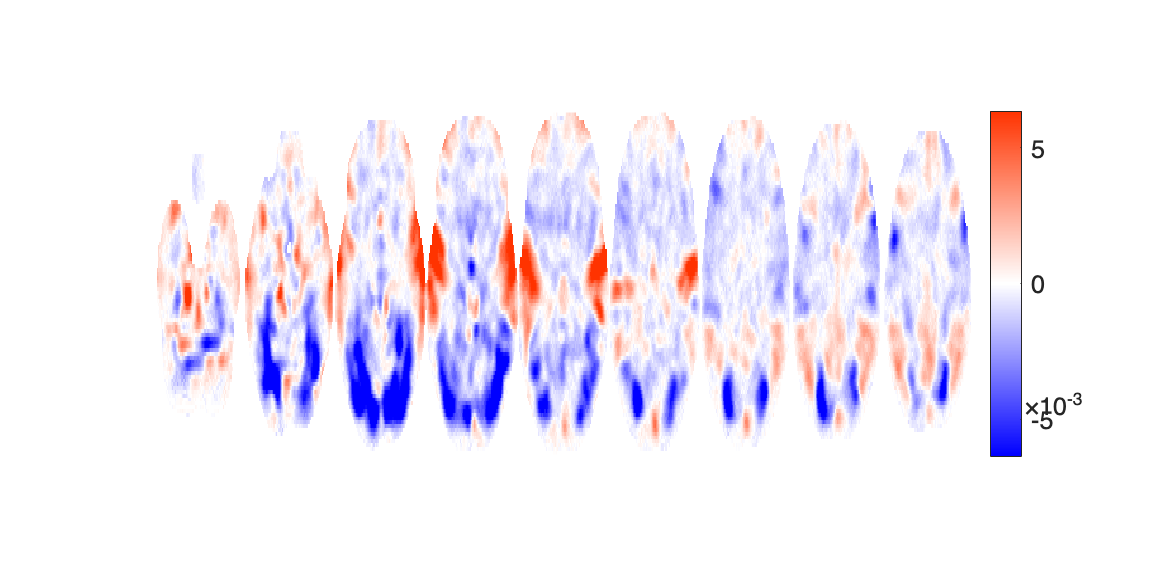


left_LGN = select_atlas_subset(LGN, {'Thal_LGN_L'});
right_LGN = select_atlas_subset(LGN, {'Thal_LGN_R'});

% LGN_regions = atlas2region(LGN);
% left_LGN = LGN_regions(1);

% orthviews(LGN)
montage(LGN, 'regioncenters');

% montage(LGN, 'compact2');

As an example, here we can leave the regions unthresholded, so their extent will be maximal. Any voxel with >0% probability of being labeled MGN will be included. MPathI will find patterns within these regions.

Compressed NIfTI files are not supported.


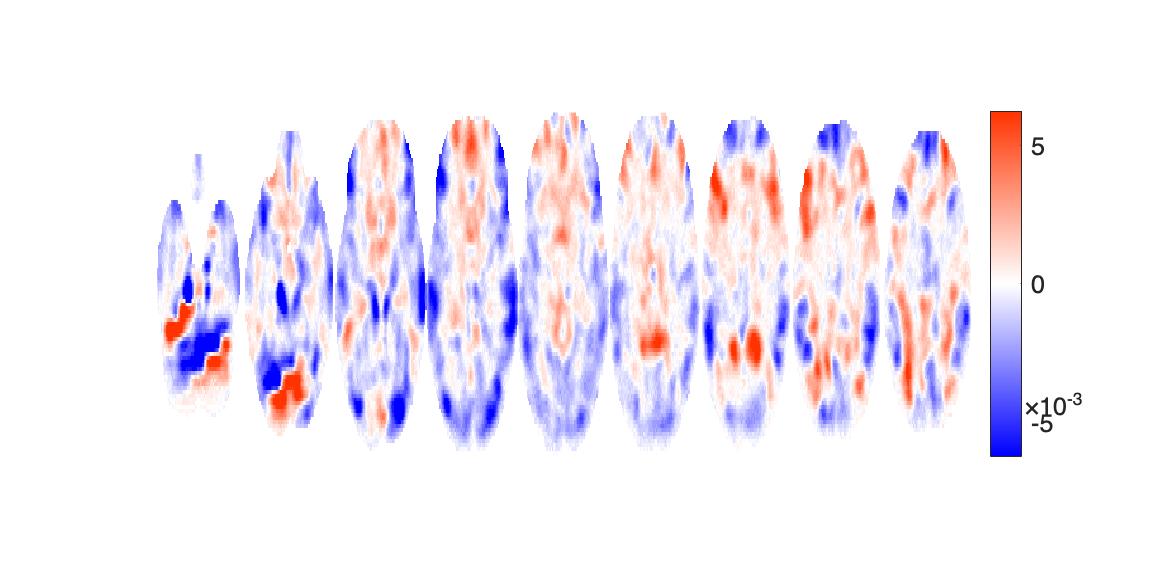

MGN = select_atlas_subset(atlas_obj, {'MGN'});
% MGN = threshold(MGN, 0.9); 

left_MGN = select_atlas_subset(MGN, {'Thal_MGN_L'});
right_MGN = select_atlas_subset(MGN, {'Thal_MGN_R'});

% orthviews(MGN)
montage(MGN, 'regioncenters');

% montage(MGN, 'compact2');

V1 is a very large region, so we can threshold it more aggressively.

RV1 = select_atlas_subset(atlas_obj, {'Ctx_V1_R'});
RV1 = threshold(RV1, 0.5); 

Keeping probability_map values above 0.50


LV1 = select_atlas_subset(atlas_obj, {'Ctx_V1_L'});
LV1 = threshold(LV1, 0.5);

Keeping probability_map values above 0.50


Compressed NIfTI files are not supported.


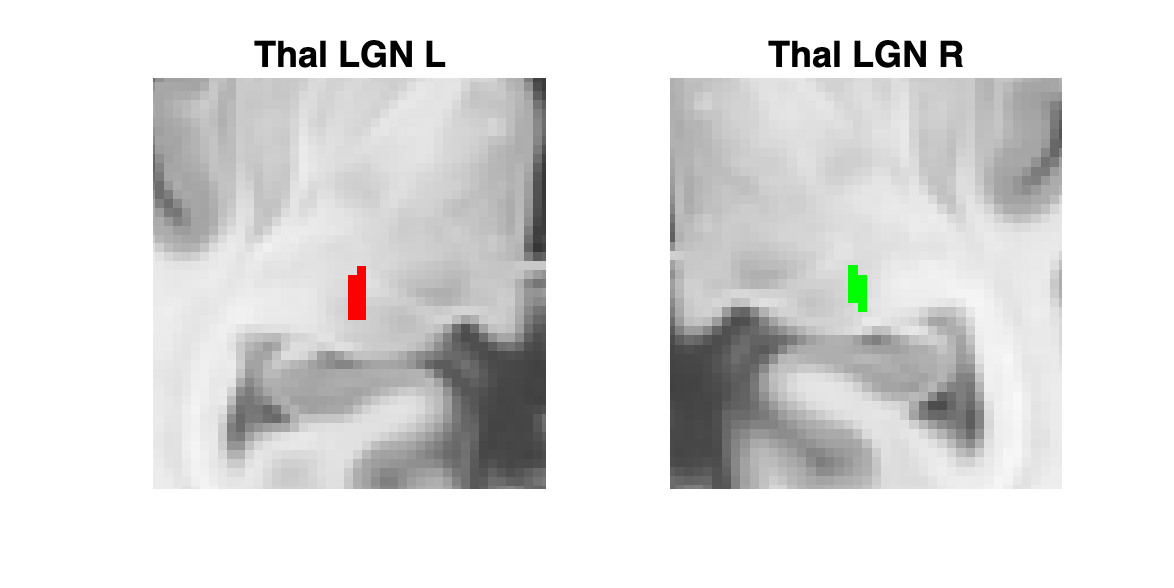


% orthviews(RV1)
montage(RV1, 'regioncenters');

Compressed NIfTI files are not supported.


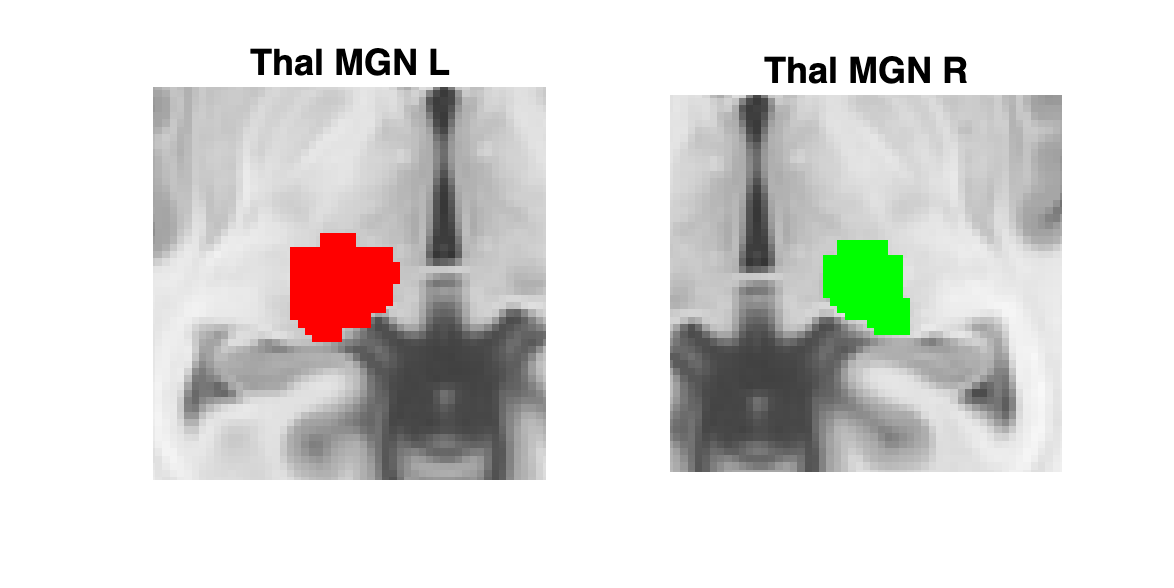

RA1 = select_atlas_subset(atlas_obj, {'Ctx_A1_R'});
% RA1 = threshold(RA1, 0.5); 
LA1 = select_atlas_subset(atlas_obj, {'Ctx_A1_L'});
% orthviews(RA1)
montage(RA1, 'regioncenters');

## 5. Run MPathI 

### Estimate the model

The method for running MPathI is called `model_brain_pathway`. This is a method for the CANlab **fmri_data()** class object.  You'll pass in an fmri_data object containing the data to extract and run analyses on (`obj_to_analyze`) as the first argument, and CANlab **atlas()** class objects defining the regions to connect.  For more information on these objects and CANlab tools, see [canlab.github.io](http://canlab.github.io) and the [CANlab Core Tools github repository](https://github.com/canlab/CanlabCore). 

- **Analysis choices**: You can run MPathI on a **group analysis**, across images from multiple subjects, or **individualized analyses**, in which each subject is run separately with model_brain_pathway and gets their own pattern. You can also use **hyperalignment** in a group analysis to functionally align each subject's functional patterns.

- In **group analysis**, you would stack multiple images per subject into a single analysis. You should specify a variable ("subjid", see below) that indicates which images belong to which subjects, so that models are always trained on some subjects and tested on others, for valid statistics. The latent patterns V and Z are constrained to be the same across individuals.

- In **individualized analysis**, you would run model_brain_pathways separately on time series images from each subject separately. The latent patterns V and Z are different for each individual, making the analysis more robust to inter-individual variability in the location of function regions and/or ideographic topographic patterns. After running the analysis on a series of subjects, you can test the summary connectivity statistics across individual participants in a second-level summary statistics group analysis.  

- **Cross-validation**: MPathI estimates cross-validated latent pathways, as well as cross-validated simple correlations across region averages.

- The default is 10-fold image-wise cross-validation, which is used here but may not be appropriate for time series connectivity (due to autocorrelation) or group analyses with multiple images for each person. The recommendation for single-person time series is rolling HVG block holdout (a custom set) or for group time series is leave-whole-person out.

- Entering `'Indices', subjid, `where subjid is an integer vector whose values denote the person each image belongs to, estimates the pathways in a leave-whole-person-out cross-validated fashion, training on some individual participants and testing on others.

- **Using the output**: You can (1) use and report the cross-validated t-test results if cross-validation folds are specified correctly; (2) analyze summary statistics from a series of individual-subject models; (3) Use the latent image series (often time series) values from source and target regions for each pathway in time series analyses, including **dynamic connectivity** and task-evoked psychophysiological interaction analyses (**PPI**), to test moderation of pathway connectivity by task events, among other uses.

**Thalamocortical connections**

- The code below runs MPathI on left-sided thalamocortical connections, identifying connetivity in the visual pathway  (LGN -> V1) and auditory pathway  (MGN -> A1)

- The code automatically tests whether connectivity in target pathways is stronger than connectivity off-target (e.g., LGN -> A1 and MGN -> V1), which should not be strongly connected

- The code automatically extracts simple ROI averages as well, and compares on-target to off-target connections


% Run MPathI
% This estimates PLS models with two pathways: left lgn->L V1 and left mgn->L A1
% It tests the cross-validated connectivity strength in each pathway
% and across pathways (off=target), and compares target vs off-target pathways

dashes = '----------------------------------------------';
printhdr = @(str) fprintf('%s\n%s\n%s\n', dashes, str, dashes);

printhdr('MPathI: left lgn->L V1 and left mgn->L A1')

----------------------------------------------
MPathI: left lgn->L V1 and left mgn->L A1
----------------------------------------------



tic

pathwaynames = {'L LGN->L V1' 'L LGN->L A1' 'L MGN->L V1' 'L MGN->L A1'};

stats = model_brain_pathway(obj_denoised, left_LGN, left_MGN, LV1, LA1);

toc

Elapsed time is 2.056699 seconds.


disp(stats.stats_report)

Latent MPathI correlations were 0.29 (sd = 0.07) for Pathway 1 and 0.19 (sd = 0.06) for Pathway 2.                                         
Correlations were  significant for Pathway 1, t(9.0) = 3.69, p = 0.004961, and  significant for Pathway 2, t(9.0) = 2.90, p = 0.017690.    
The interaction between on-targed (expected) and off-target pathways was  signficant, t(9.0) = 4.67, p = 0.001164.                         
Pathway 1 on-target vs. off-target correlations were  signficant, t(9.0) = 3.84, p = 0.003965.                                             
Pathway 2 on-target vs. off-target correlations were not signficant, t(9.0) = 2.20, p = 0.055589.                                          
                                                                                                                                           
Simple ROI correlations were -0.26 (sd = 0.07) for Pathway 1 and 0.08 (sd = 0.08) for Pathway 2.                                           
Correlations were  s

#### Show results for region averages and latent pathways

- You can also use the 'plot' option to do this automatically

colors = {[.3 .4 1] [.4 .5 .6] [.6 .5 .4] [1 .7 .3]};

% Plot the correlations among region averages:
disp('Simple ROI correlations')

Simple ROI correlations


create_figure('Simple ROI correlations');

barplot_columns(stats.simple_correlations, 'names', pathwaynames, 'colors', colors, 'nofigure');

Col   1: L LGN->L V1	Col   2: L LGN->L A1	Col   3: L MGN->L V1	Col   4: L MGN->L A1	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
         Name          Mean_Value    Std_Error       T           P        Cohens_d
    _______________    __________    _________    _______    _________    ________

    {'L LGN->L V1'}     -0.26368     0.070561     -3.7369    0.0046473    -1.1817 
    {'L LGN->L A1'}     0.064297     0.093736     0.68593      0.51004    0.21691 
    {'L MGN->L V1'}     0.087654     0.071793      1.2209      0.25313    0.38609 
    {'L MGN->L A1'}     0.083161     0.081538      1.0199       0.3344    0.32252 



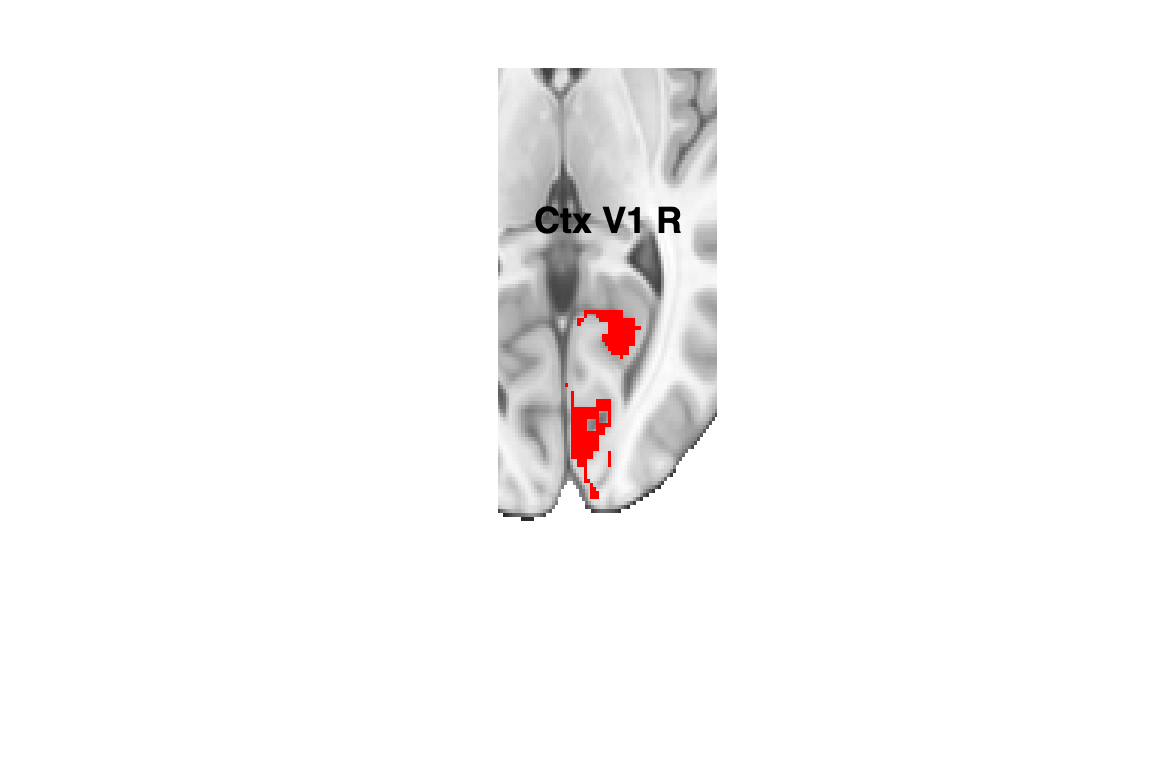

title('Simple ROI correlations')


% Plot the correlations among PLS-optimized latent timeseries:
disp('MPathI correlations')

MPathI correlations


create_figure('MPathI correlations');

barplot_columns(stats.latent_correlations, 'names', pathwaynames, 'colors', colors, 'nofigure');

Col   1: L LGN->L V1	Col   2: L LGN->L A1	Col   3: L MGN->L V1	Col   4: L MGN->L A1	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
         Name          Mean_Value    Std_Error       T            P        Cohens_d
    _______________    __________    _________    ________    _________    ________

    {'L LGN->L V1'}      0.28785     0.073706       3.9053    0.0035901       1.235
    {'L LGN->L A1'}    0.0058967     0.081201     0.072619       0.9437    0.022964
    {'L MGN->L V1'}    -0.089409     0.090155     -0.99172      0.34725    -0.31361
    {'L MGN->L A1'}      0.19449     0.064426       3.0188     0.014507     0.95463



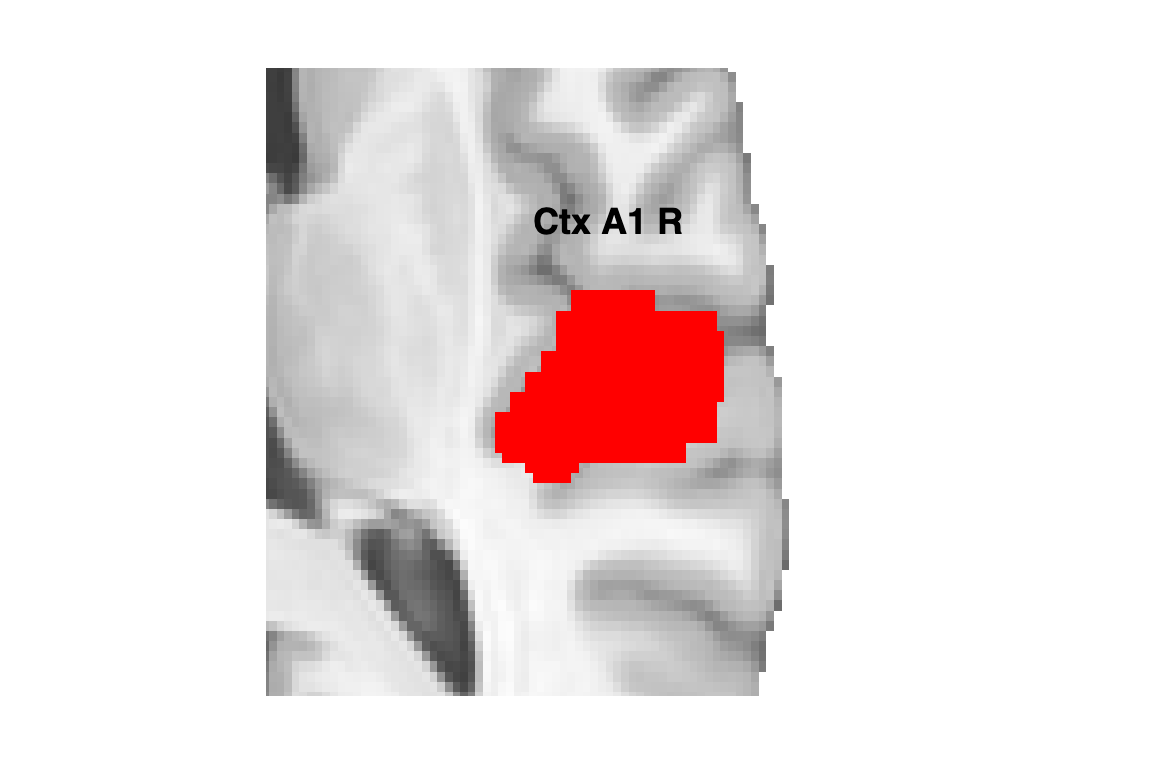

title('MPathI correlations')

## 6. Understanding the output

 MPathI returns a **stats** structure including a collection of output. 

**Cross-validated correlations**

- Outputs with 4 columns contain results for [Path 1, Offtarget1, Offtarget2, Path 2] in that order. Pathway results are columns 1 and 4.  Off-target pathways are columns 2 and 3.

- **simple_correlations**: correlations results of cross-validated connectivity analysis that used region averages. One row per fold. Pathways are columns 1 and 4.  Off-target pathways are columns 2 and 3. If your train/test folds are independent (no correlated errors), you can do t-tests across folds for on-target pathways and on-target vs. off-target correlations. These are calculated automatically on Fisher's z-transformed correlations. 

- **latent_correlations**: cross-validated correlations among PLS-optimized latent image series (T_hat and U_hat). One row per fold. T-tests on pathways apply as above.

**Latent image series and voxel patterns**

- **latent_timeseries**: cross-validated image series of the latent scores

- **latent_timeseries_source**: T_hat = Y_test * V.  Columns 1 and 4 are Path 1 and Path 2, respectively

- **latent_timeseries_target**: U_hat = X_test * Z. Columns 1 and 4 are Path 1 and Path 2, respectively

- **Z_pathway_one/four**: estimated latent patterns in source regions for Path 1 and Path 2, respectively

- **V_pathway_one/four**: estimated latent patterns in target regions for Path 1 and Path 2, respectively

**Overall cross-validated correlations and dot products for multi-level analysis**.  If you run MPathI on a series of individual subjects, each with their own latent pattern, then you can use these as summary statistics for 2nd-level group analyses:

-             stats.**path1_overall_xval_r** = Correlation between path 1 source and target

-             stats.**path2_overall_xval_r** = Correlation between path 2 source and target

-             stats.**path1_overall_xval_dot** = Dot product between path 1 source and target

-             stats.**path2_overall_xval_dot** = Dot product between path 2 source and target

**T-test results **

- **latent_correlation_interaction_ttest**: T-test on Fisher-transformed latent_correlation contrasting on-target vs. off-target on two pathways

- **simple_correlation_interaction_ttest**: T-test on Fisher-transformed simple_correlation contrasting on-target vs. off-target on two pathways

- **latent_correlation_pathway_*_ttest**: T-test on Fisher-transformed latent_correlation contrasting on-target vs. off-target on pathway one or two

- **simple_correlation_pathway_*_ttest**: T-test on Fisher-transformed simple_correlation contrasting on-target vs. off-target on pathway one or two

**Bootstrapped patterns, if requested**

- PLS_bootstrap_stats_Z: statistic image for PLS regression coefficients

- PLS_bootstrap_stats_V: statistic image for PLS regression coefficients

**Source fmri_data objects for regions**

- source_one_obj (optional): resampled and masked fmri data object for source one

- source_two_obj (optional): resampled and masked fmri data object for source two

- target_one_obj (optional): resampled and masked fmri data object for target one

- target_two_obj (optional): resampled and masked fmri data object for target one

### Ways to use the output

## 7. More extensions

### Run MPathI on right-hemisphere thalamocortical connections

- Now let's test ipsilateral connections on the right side

- The 'plot' and 'names' options will print bar plots automatically

printhdr('MPathI: right lgn->L V1 and right mgn->L A1')

----------------------------------------------
MPathI: right lgn->L V1 and right mgn->L A1
----------------------------------------------


Simple ROI correlations
Col   1: R LGN->R V1	Col   2: R LGN->R A1	Col   3: R MGN->L V1	Col   4: R MGN->R A1	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
         Name          Mean_Value    Std_Error       T          P        Cohens_d
    _______________    __________    _________    _______    ________    ________

    {'R LGN->R V1'}     -0.12974      0.06864     -1.8902    0.091311    -0.59772
    {'R LGN->R A1'}     -0.10273     0.097314     -1.0557     0.31863    -0.33383
    {'R MGN->L V1'}     0.093034     0.099038     0.93938     0.37206     0.29706
    {'R MGN->R A1'}    -0.093345     0.072962     -1.2794     0.23276    -0.40457

MPathI correlations


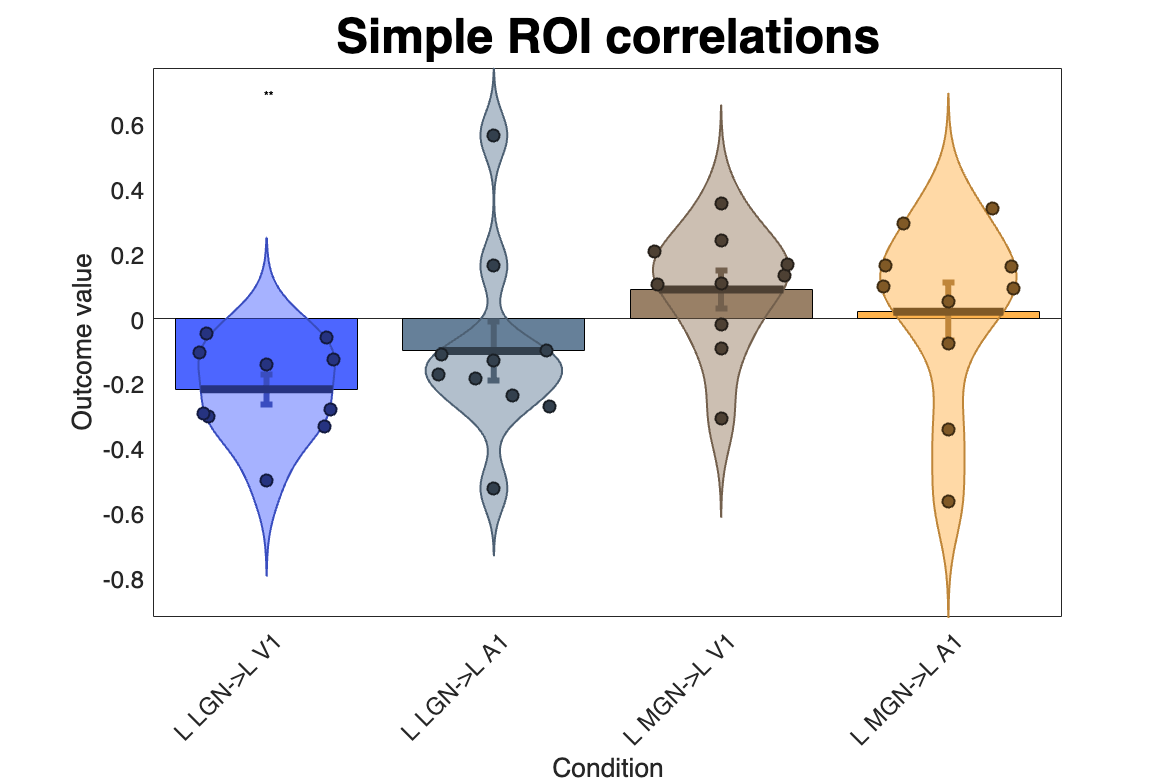

Col   1: R LGN->R V1	Col   2: R LGN->R A1	Col   3: R MGN->L V1	Col   4: R MGN->R A1	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
         Name          Mean_Value    Std_Error       T            P         Cohens_d
    _______________    __________    _________    ________    __________    ________

    {'R LGN->R V1'}      0.42608     0.076932       5.5383    0.00036182      1.7514
    {'R LGN->R A1'}     -0.34087     0.074343      -4.5851     0.0013182     -1.4499
    {'R MGN->L V1'}    -0.080079     0.094692     -0.84567       0.41965    -0.26742
    {'R MGN->R A1'}     0.069546     0.085843      0.81015       0.43875     0.25619



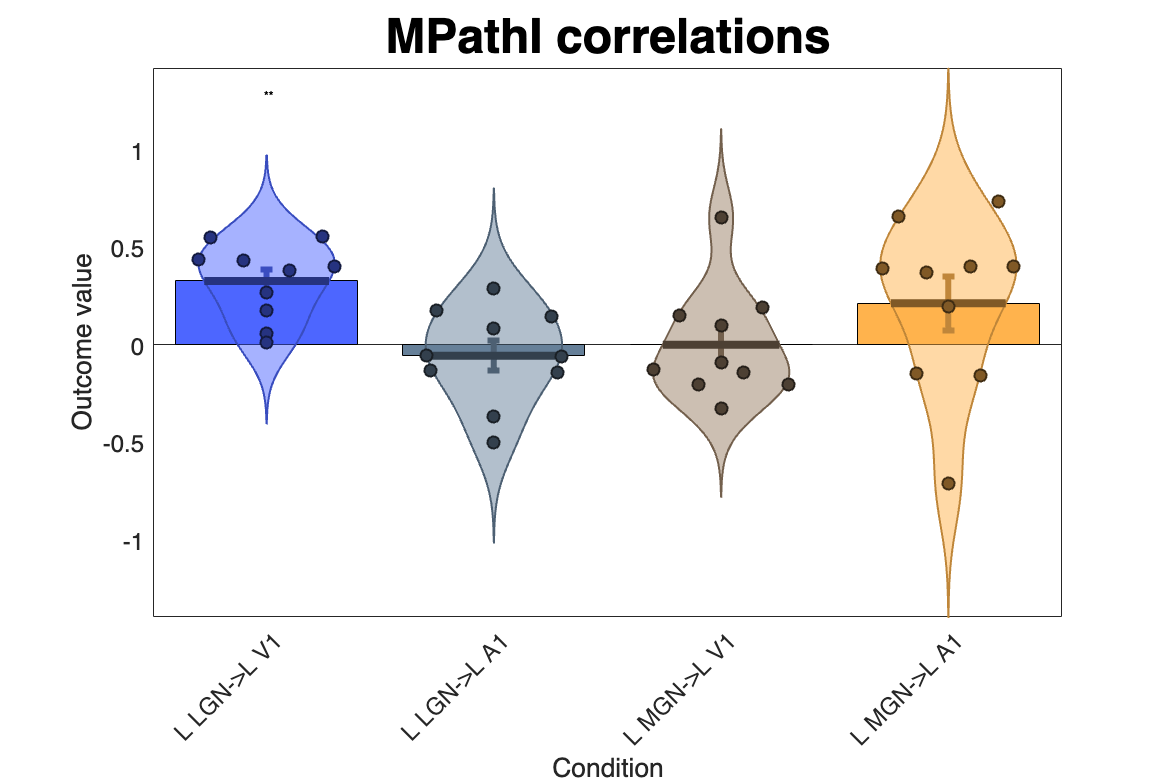

tic

pathwaynames = {'R LGN->R V1' 'R LGN->R A1' 'R MGN->L V1' 'R MGN->R A1'};

stats = model_brain_pathway(obj_denoised, right_LGN, right_MGN, RV1, RA1, 'plot', 'names', pathwaynames);


toc

Elapsed time is 2.754785 seconds.


disp(stats.stats_report)

Latent MPathI correlations were 0.43 (sd = 0.08) for Pathway 1 and 0.07 (sd = 0.09) for Pathway 2.                                             
Correlations were  significant for Pathway 1, t(9.0) = 4.92, p = 0.000830, and not significant for Pathway 2, t(9.0) = 0.83, p = 0.429275.     
The interaction between on-targed (expected) and off-target pathways was  signficant, t(9.0) = 4.72, p = 0.001096.                             
Pathway 1 on-target vs. off-target correlations were  signficant, t(9.0) = 5.45, p = 0.000405.                                                 
Pathway 2 on-target vs. off-target correlations were not signficant, t(9.0) = 0.99, p = 0.349482.                                              
                                                                                                                                               
Simple ROI correlations were -0.13 (sd = 0.07) for Pathway 1 and -0.09 (sd = 0.07) for Pathway 2.                                       

### Run MPathI on normalized images

**Compare with analysis of normalized images: **There may be lots of variance across subjects in the scale of images, which could be an issue here. Z-scoring images may help, but may also result in information loss. This kind of normalization was suggested by Bogdan Petre's analysis of cross-validated prediction of pain across studies, comparing with ComBat. 

- Z-scoring images removes the global signal mean and standard deviation from the image series

- Results should be interpreted in terms of variation around the global image mean

% Normalize each images by calculating a spatial z-score, so that each
% image is mean 0 and standard deviation 1:
printhdr('MPathI with image normalization')

----------------------------------------------
MPathI with image normalization
----------------------------------------------


Simple ROI correlations
Col   1: L LGN->L V1	Col   2: L LGN->L A1	Col   3: L MGN->L V1	Col   4: L MGN->L A1	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
         Name          Mean_Value    Std_Error       T          P        Cohens_d
    _______________    __________    _________    _______    ________    ________

    {'L LGN->L V1'}      0.10606     0.084906      1.2492     0.24311     0.39503
    {'L LGN->L A1'}     -0.22155     0.075205     -2.9459     0.01633    -0.93157
    {'L MGN->L V1'}     -0.16229     0.069865     -2.3229    0.045273    -0.73455
    {'L MGN->L A1'}      0.22861     0.074401      3.0727    0.013296     0.97167

MPathI correlations


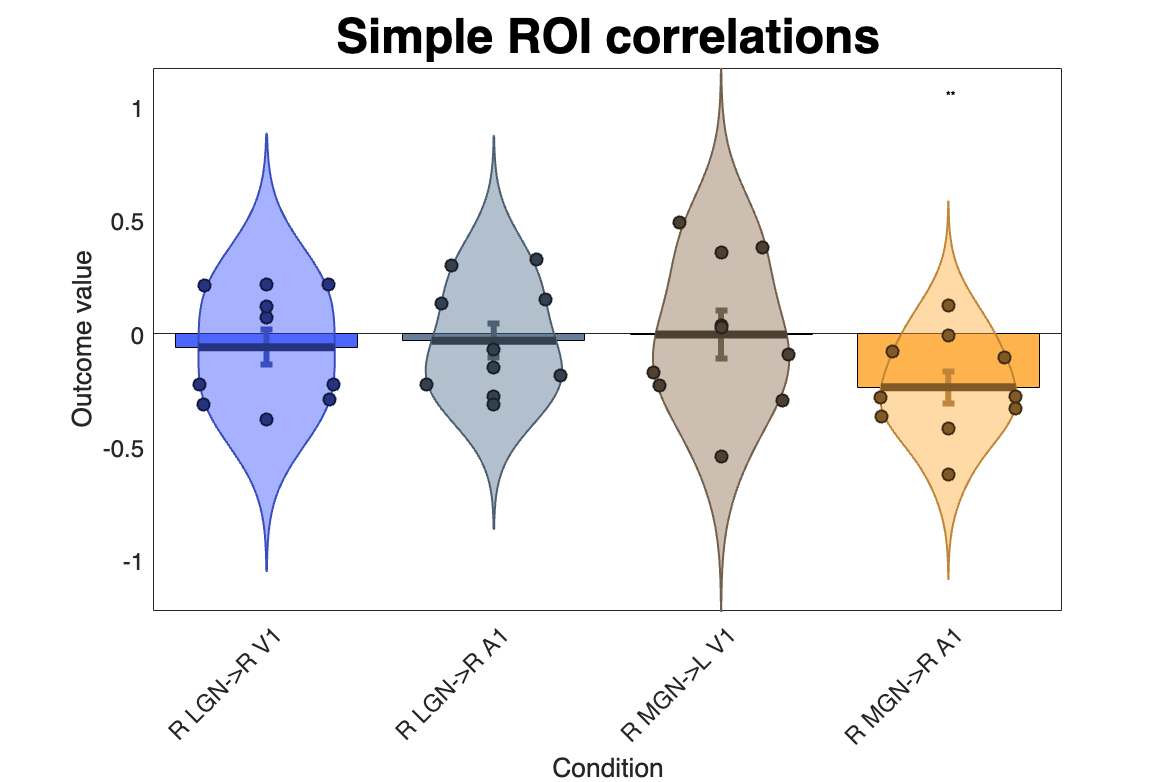

Col   1: L LGN->L V1	Col   2: L LGN->L A1	Col   3: L MGN->L V1	Col   4: L MGN->L A1	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
         Name          Mean_Value    Std_Error       T            P         Cohens_d 
    _______________    __________    _________    ________    __________    _________

    {'L LGN->L V1'}      0.48094     0.071186       6.7561    8.3074e-05       2.1365
    {'L LGN->L A1'}     -0.37693     0.075485      -4.9935    0.00074554      -1.5791
    {'L MGN->L V1'}    -0.015618     0.096565     -0.16174       0.87508    -0.051147
    {'L MGN->L A1'}      0.21228     0.052262       4.0619     0.0028338       1.2845



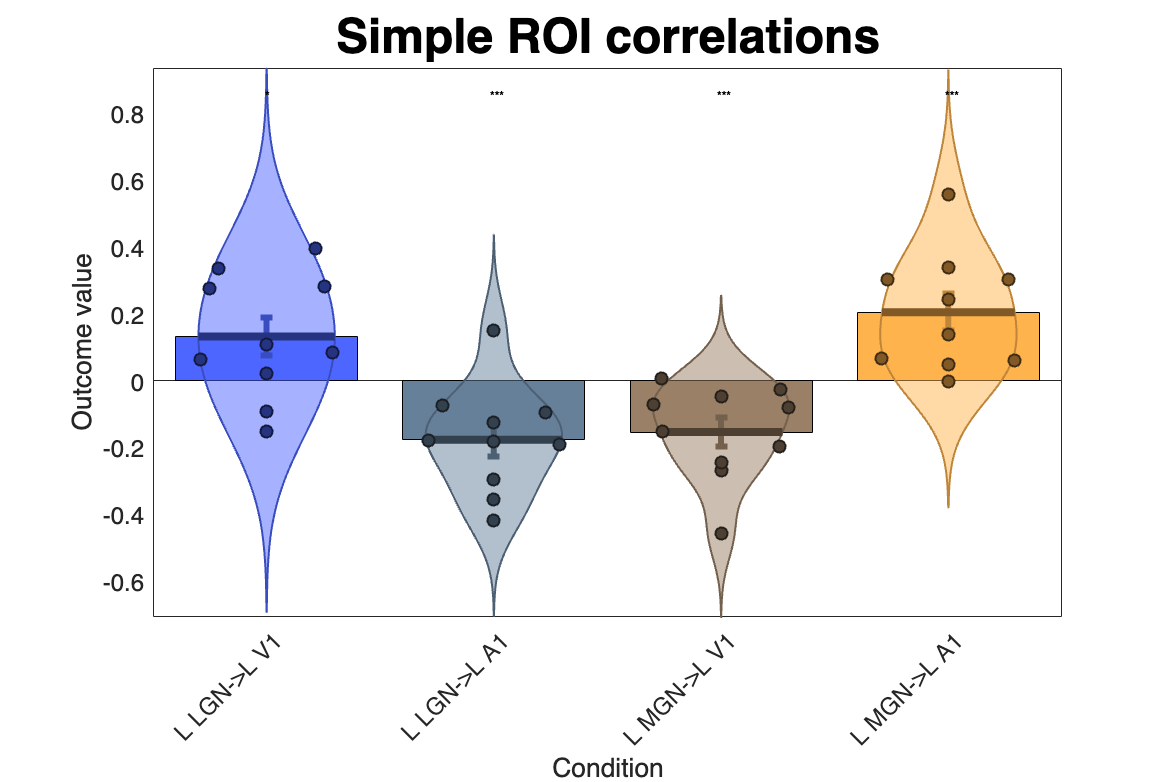


obj_denoised_z = rescale(obj_denoised, 'zscoreimages');

pathwaynames = {'L LGN->L V1' 'L LGN->L A1' 'L MGN->L V1' 'L MGN->L A1'};

tic
statsz = model_brain_pathway(obj_denoised_z, left_LGN, left_MGN, LV1, LA1, 'plot', 'names', pathwaynames);

toc

Elapsed time is 1.860473 seconds.



disp(statsz.stats_report);

Latent MPathI correlations were 0.48 (sd = 0.07) for Pathway 1 and 0.21 (sd = 0.05) for Pathway 2.                                        
Correlations were  significant for Pathway 1, t(9.0) = 5.54, p = 0.000362, and  significant for Pathway 2, t(9.0) = 3.96, p = 0.003306.   
The interaction between on-targed (expected) and off-target pathways was  signficant, t(9.0) = 5.90, p = 0.000230.                        
Pathway 1 on-target vs. off-target correlations were  signficant, t(9.0) = 5.94, p = 0.000218.                                            
Pathway 2 on-target vs. off-target correlations were not signficant, t(9.0) = 2.10, p = 0.064706.                                         
                                                                                                                                          
Simple ROI correlations were 0.11 (sd = 0.08) for Pathway 1 and 0.23 (sd = 0.07) for Pathway 2.                                           
Correlations were not signi

### Bootstrap tests for inferences on model (latent multivariate pattern) weights

- MPathI allows bootstrapping to obtain P-values and threshold latent pattern weights

- This walkthrough does not cover this, as it uses only a single-subject example time series dataset, but a code example is below

function obj_denoised = clean_fmri_timeseries(obj, mvmtfname)
% Obtain a matrix of 'spike' indicators and movement-related regressors 
% based on multiple criteria to use as covariates

% 24 movement-related covariates per run

[mvmt_matrix, mvmt_regs_24] = movement_regressors(mvmtfname);

covs = mvmt_regs_24;

% 'spike' outliers and high framewise-displacement (fd) images
[est_outliers_uncorr, est_outliers_corr, outlier_tables] = outliers(obj, 'fd', mvmt_matrix);
sum(est_outliers_uncorr) % this shows how many outliers

covs = [covs outlier_tables.outlier_regressor_matrix_uncorr];

% Mean CSF
[gwcsfvalues, gwcsfcomponents] = extract_gray_white_csf(obj);
meancsf = gwcsfvalues(:, 3);
covs = [covs meancsf];

% Here the first component is a head-shift artifact; this will not always
% be the case. You could use PCA or ICA denoising strategies but be
% careful.  This code applies to this sample data only.
[component_scores, eigenmap_obj, explained] = pca(obj, 'k', 3);
covs = [covs component_scores(:, 1)];

% High-pass filter - assume TR = 2 sec
[S,KL,KH] = use_spm_filter(2, size(obj.dat, 2),'none', 'specify', 128);

covs = [covs KH];

% Regress all covs out from each voxel and return residuals
% We can ignore colinearity/leverage warnings

obj.X = covs;
regress_output = regress(obj, 'residual', 'noverbose');
obj_denoised = regress_output.resid;

end % function
